# Part 1

Now let's solve a simple boundary-value problem:

Let $\Omega = (0, 1)$. 


$$\frac{d^2 u}{d x^2} + f = 0 \\
u(1) = g \\
\frac{d u}{d x}(0) = h
$$


clear
close all

x = sym( "x", "real" );
f(x) = x^0; %piecewise( ( -0.25 <= x ) & ( x <= 0.25 ), 1, 0 );
g = 0;
h = 0;
domain = [0, 1];
boundary_tol = 1e-6;
penalty = 1e12;
degree = 4;
basis_family = "Chebyshev";

[u, M, F, N, d] = LaplaceEquation( basis_family, degree, domain, f, g, h, boundary_tol, penalty );
exactSolution = ExactLaplaceSolution( f, g, h, domain );
l2_error = ComputeL2Error( exactSolution.U, simplify( u ), domain );
l2_error = vpa( simplify( abs( l2_error ) ), 16 )

$$l2\_error = 0.0000006355126918426971$$

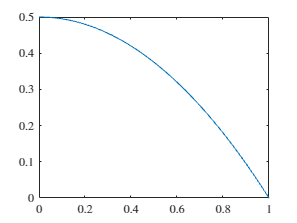


figure
hold on
fplot( exactSolution.U, domain, Color="k" )
fplot( u, domain, SeriesIndex=1 )

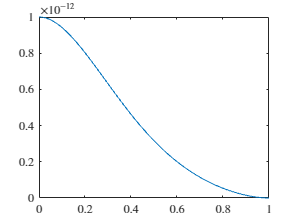


figure
fplot( ( exactSolution.U - u )^2, domain )

clear
close all

x = sym( "x", "real" );
f(x) = x^0; %piecewise( ( -0.25 <= x ) & ( x <= 0.25 ), 1, 0 );
g = 0;
h = 0;
domain = [0, 1];
boundary_tol = 1e-6;
penalty = 1e12;
degree = 4;
basis_family = "Chebyshev";
[u, M, F, N, d] = HeatEquation( basis_family, degree, domain, f, g, h, boundary_tol, penalty );

exactSolution = ExactHeatSolution( f, g, h, domain );
l2_error = ComputeL2Error( exactSolution.U, simplify( u ), domain );
l2_error = vpa( simplify( abs( l2_error ) ), 16 )

$$l2\_error = 0.0000006355126918426971$$


figure
hold on
fplot( exactSolution.U, domain, Color="k" )
fplot( u, domain, SeriesIndex=1 )


figure
fplot( ( exactSolution.U - u )^2, domain )

clear
close all

x = sym( "x", "real" );
domain = [0, 1];

E = 1e3;
I = 1/12;
f(x) = 1e-3 * x ^ 1;
M = 2e-2;
Q = 5e-3;

exactSolution = ExactBernoulliEulerBeamSolution( E, I, f, M, Q, domain );

degree = 4;
displacement_constraint = 0;
slope_constraint = 0;
boundary_tol = 1e-6;
penalty = 1e12;
basis_family = "Chebyshev";
approxSolution = BernoulliEulerBeamEquation( basis_family, degree, domain, E, I, displacement_constraint, slope_constraint, f, M, Q, boundary_tol, penalty );

l2_error = ComputeL2Error( exactSolution.U, simplify( approxSolution ), domain );
l2_error = vpa( simplify( abs( l2_error ) ), 16 )

$$l2\_error = 0.0000001721607124904708$$

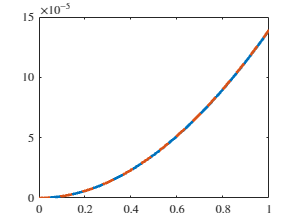


figure
hold on
fplot( exactSolution.U, domain, LineStyle="-", LineWidth=2 )
fplot( approxSolution, domain, LineStyle="--", LineWidth=2 )

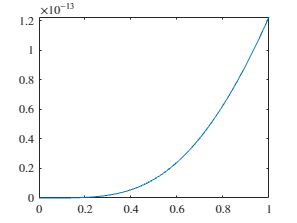


figure
fplot( ( exactSolution.U - approxSolution )^2, domain )

clear
close all

x = sym( "x", "real" );
domain = [0, 1];

f(x) = 1*x^0;
a = 0;
b = 0;
c = 0;

exactSolution = ExactThirdOrderSolution( f, a, b, c, domain )

exactSolution = struct with fields:
         f: [1×1 symfun]
       eqn: [1×1 symfun]
      cond: [u(0) == 0    subs(diff(u(x), x), x, 0) == 0    subs(diff(u(x), x, x), x, 0) == 0]
    domain: [0 1]
         U: [1×1 symfun]



degree = 4;
boundary_tol = 1e-6;
penalty = 1e12;
basis_family = "Chebyshev";
approxSolution = ThirdOrderPDE( basis_family, degree, domain, f, a, b, c, boundary_tol, penalty )

$$approxSolution(x) = \frac{22892509464767458915709017944867022536790647524957519528008391601562273080029296867732031249999911406250000000000000}{439536914283105524922080839884535044507744510801037705504465129758075101587794525000787509450000000000150000000000001}-\frac{572312164307060320587158308503112792979651184082031734497070312508074951171875000000000000000000000000000000\,\left(4\,x-2\right)\,\left(\left(\left(2\,x-1\right)\,\left(4\,x-2\right)-1\right)\,\left(4\,x-2\right)-2\,x+1\right)}{439536914283105524922080839884535044507744510801037705504465129758075101587794525000787509450000000000150000000000001}-\frac{2289253235725403123474981994688052556169301459477050781271963867187500507568359375004101562500000000000000000000000\,\left(\left(2\,x-1\right)\,\left(4\,x-2\right)-1\right)\,\left(4\,x-2\right)}{439536914283105524922080839884535044507744510801037705504465129758075101587794525000787509450000000000150000000000001}-\frac{13735507395796968274269170379980348378092466521392517089779311889648433066851806640538867187500000000000000000000000\,\left(2\,x-1\right)\,\left(4\,x-2\right)}{439536914283105524922080839884535044507744510801037705504465129758075101587794525000787509450000000000150000000000001}-\frac{64099017344281000050035257562531256175603756984458658787072097656249590881445312490566406249999921250000000000000000\,x}{439536914283105524922080839884535044507744510801037705504465129758075101587794525000787509450000000000150000000000001}$$


l2_error = ComputeL2Error( exactSolution.U, simplify( approxSolution ), domain );
l2_error = vpa( simplify( abs( l2_error ) ), 16 )

$$l2\_error = 0.0000001130776206653161$$

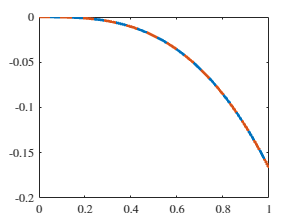


figure
hold on
fplot( exactSolution.U, domain, LineStyle="-", LineWidth=2 )
fplot( approxSolution, domain, LineStyle="--", LineWidth=2 )

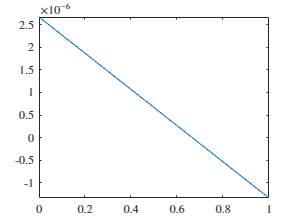


figure
fplot( diff( approxSolution, 3 ) + f, domain )